clear

addpath('functions\')

#### Compute $\Phi$

freqs = [1000 2000 4000 16000]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

Model = myModel;

freqs = reshape(freqs, 1,1,[]);
M = length(Model.sensors.placement_phi);
N = length(Model.mesh.voxel_volumes);
Phi = zeros(M, N, length(freqs));

rho = Model.mesh.gauss_nodes(1,:,:);
phi = Model.mesh.gauss_nodes(2,:,:);
z   = Model.mesh.gauss_nodes(3,:,:);

for k = 1:length(freqs)
    tic
    Model = ComsolInterface('Build', Model);
    ComsolInterface('Solve', Model, freqs(k), mesh_size)
    [Ephi1, Ez1] = ComsolInterface('EvaluateField', Model, {'Ephi' 'Ez'}, rho,phi,z);

    Model = ComsolInterface('Build', Model, 'sensor1');
    ComsolInterface('Solve', Model, freqs(k), mesh_size)
    [Ephi2, Ez2] = ComsolInterface('EvaluateField', Model, {'Ephi' 'Ez'}, rho,phi,z);

    S_sigma = mean(dot([Ephi1;Ez1], [Ephi2;Ez2]), 3) .* Model.mesh.voxel_volumes;
    Phi(1,:,k) = -S_sigma * Model.pipe.sigma;
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freqs(k), toc)
end

Compute 1000 Hz sensitivity took 36.95 seconds
Compute 2000 Hz sensitivity took 35.84 seconds
Compute 4000 Hz sensitivity took 36.04 seconds
Compute 16000 Hz sensitivity took 35.86 seconds


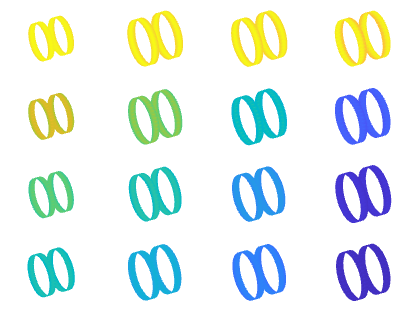


voxels_corner = Model.mesh.voxel_corners;
voxels_center = mean(voxels_corner, 3);
rho = voxels_center(1,:);
phi = voxels_center(2,:);
z   = voxels_center(3,:);
sensor_phi = Model.sensors.placement_phi;

eps = 1e-8;
for i = 2:M
for j = 1:N
    n = abs(rho - rho(j)) < eps & ...
        abs(wrapToPi( phi - phi(j) + (sensor_phi(i) - sensor_phi(1)) )) < eps & ...
        abs(z - z(j)) < eps;
    n = find(n);
    Phi(i,j,:) = Phi(1,n,:);
end
end

fname = sprintf('data/Phi_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'freqs','Phi','voxels_corner', "-v7.3");

plot_sensitivity(fname)